E_struct = expCell{3};

idapproach1 = find(strcmp(E_struct{1}.Behavior.EventNames, 'approach'));
idapproach2 = find(strcmp(E_struct{2}.Behavior.EventNames, 'approach'));
idsniff1 = find(strcmp(E_struct{1}.Behavior.EventNames, 'sniffing'));
idsniff2 = find(strcmp(E_struct{2}.Behavior.EventNames, 'sniffing'));


M1_init_onset = E_struct{1,1}.Behavior.OnsetTimes{idapproach1};
M2_init_onset = E_struct{1,2}.Behavior.OnsetTimes{idapproach2};
M1_init_offset = E_struct{1,1}.Behavior.OffsetTimes{idapproach1};
M2_init_offset = E_struct{1,2}.Behavior.OffsetTimes{idapproach2};

M1_inves_offset = E_struct{1,1}.Behavior.OffsetTimes{idsniff1};
M2_inves_offset = E_struct{1,2}.Behavior.OffsetTimes{idsniff2};
M1_inves_onset = E_struct{1,1}.Behavior.OnsetTimes{idsniff1};
M2_inves_onset = E_struct{1,2}.Behavior.OnsetTimes{idsniff2};


% interval offset-->onset
% M1 interval
M1_interval = [];
M1_pre_invest = [];
M1_approach_counted = [];
for i = 1:length(M1_init_onset)
    this_on = M1_init_onset(i); % initiate approaching
    last_off = find(M1_inves_offset<this_on,1, 'last'); % where last sniffing is over
    if and(~isempty(last_off), M1_inves_offset(last_off)>M1_init_offset(max(i-1,1)))
        M1_interval = [M1_interval, this_on-M1_inves_offset(last_off)];
        M1_pre_invest = [M1_pre_invest, M1_inves_offset(last_off) - M1_inves_onset(last_off)];
        M1_approach_counted = [M1_approach_counted, M1_init_onset(i)];
    end
end

M2_interval = [];
M2_pre_invest = [];
M2_approach_counted = [];
for i = 1:length(M2_init_onset)
    this_on = M2_init_onset(i);
    last_off = find(M2_inves_offset<this_on,1, 'last');
    if and(~isempty(last_off), M2_inves_offset(last_off)>M2_init_offset(max(i-1,1)))
        M2_interval = [M2_interval, this_on-M2_inves_offset(last_off)];
        M2_pre_invest = [M2_pre_invest, M2_inves_offset(last_off) - M2_inves_onset(last_off)];
        M2_approach_counted = [M2_approach_counted, M2_init_onset(i)];
    end
end

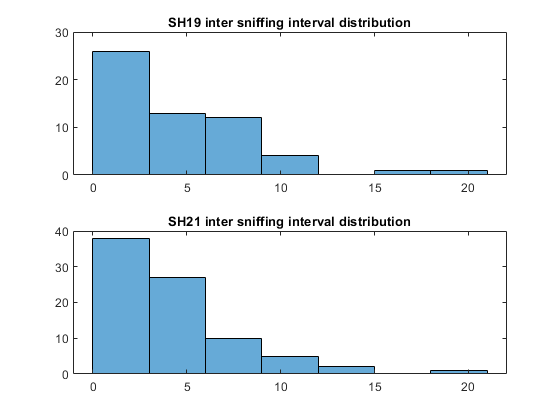

% histograms 
subplot(2,1,1), histogram(M1_interval/30), title('SH19 inter sniffing interval distribution');
subplot(2,1,2), histogram(M2_interval/30), title('SH21 inter sniffing interval distribution')

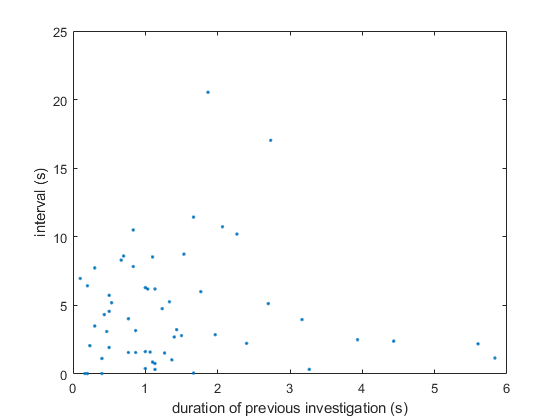


% relationship of interval vs length of previous investigation
figure, plot(M1_pre_invest/30, M1_interval/30,'.'), ylabel('interval (s)'), xlabel('duration of previous investigation (s)');

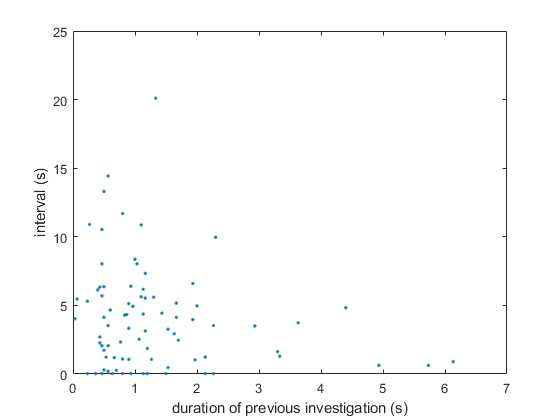

figure, plot(M2_pre_invest/30, M2_interval/30,'.'), ylabel('interval (s)'), xlabel('duration of previous investigation (s)');


corr2(M1_pre_invest, M1_interval)

ans = 0.0043

corr2(M2_pre_invest, M2_interval)

ans = -0.1706

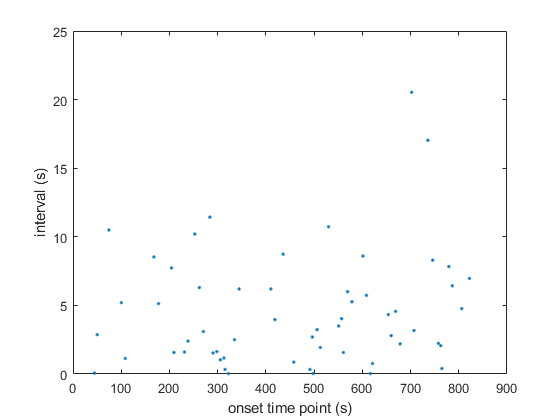


% trend of interval over time
figure, plot(M1_approach_counted/30, M1_interval/30, '.'), ylabel('interval (s)'), xlabel('onset time point (s)');

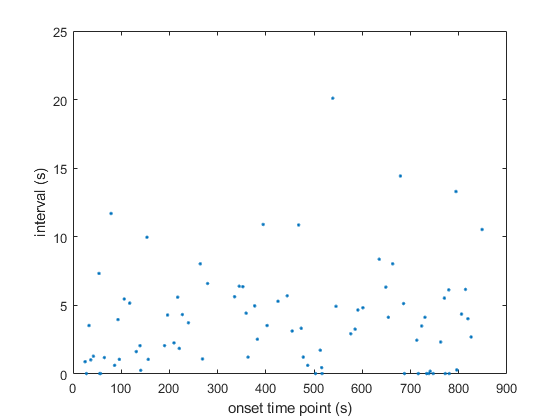

figure, plot(M2_approach_counted/30, M2_interval/30, '.'), ylabel('interval (s)'), xlabel('onset time point (s)');

corr2(M1_approach_counted, M1_interval)

ans = 0.1510

corr2(M2_approach_counted, M2_interval)

ans = 0.1127

% both have positive pcc, meaning the late in the phase, the longer the
% period is

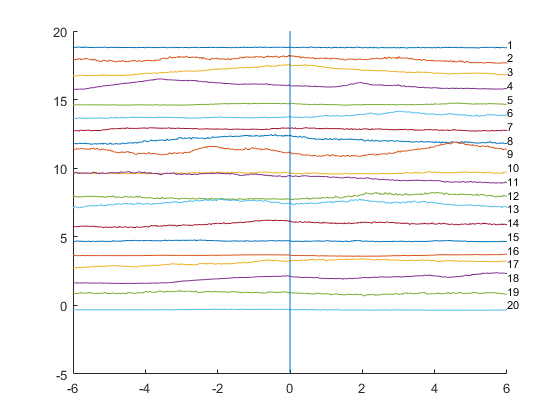

% plot average neuron activities +- 3s of investigation onset
% M1
PlotResponseCurve(E_struct{1}, 'sniffing', 1:20, 6);

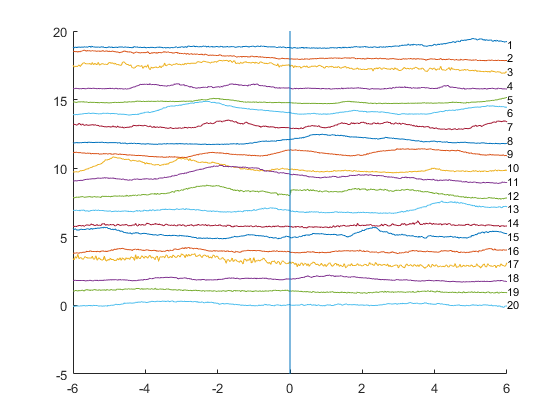

PlotResponseCurve(E_struct{2}, 'sniffing', 1:20, 6);

% first calculate pcc in/out interaction
[inves_corr_in, inves_corr_out] = Corr_Behav(E_struct{1}, E_struct{2}, {'trypassing','trypassing'});
inves_corr_out

inves_corr_out = -0.0179

inves_corr_in

inves_corr_in = -0.3438

DM1 = zscore(E_struct{1}.DataMatrix);
DM2 = zscore(E_struct{2}.DataMatrix);

% figure out percentage cells showed synergistic activity rather than
% find cells that significantly increased their activity during
% social engagement
M1_invest_logical = E_struct{1}.Behavior.LogicalVecs{idsniff1};
M2_invest_logical = E_struct{2}.Behavior.LogicalVecs{idsniff2};

M1_invest_logical = M1_invest_logical(1:min(length(M1_invest_logical),length(M2_invest_logical)));
M2_invest_logical = M2_invest_logical(1:min(length(M1_invest_logical),length(M2_invest_logical)));


social_logicalo = M1_invest_logical.*M2_invest_logical;
posID1 = [];
parfor p = 1:size(DM1,2)
    c = DM1(:,p);
    social_logical = social_logicalo(1:length(c));
    dt = [];
    for i = 1:3000
        temp = circshift(c,randperm(50000,1));
        dt = [dt, sum(temp(social_logical>0))];
    end
%     figure,
%     histogram(dt);
    if sum(c(social_logical>0)) >= quantile(dt, 0.75)
%         fprintf('%i is positive\n', p);
        posID1 = [posID1, p];
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


posID2 = [];
parfor p = 1:size(DM2,2)
    c = DM2(:,p);
    social_logical = social_logicalo(1:length(c));
    dt = [];
    for i = 1:3000
        temp = circshift(c,randperm(50000,1));
        dt = [dt, sum(temp(social_logical>0))];
    end
%     figure,
%     histogram(dt);
    if sum(c(social_logical>0)) >= quantile(dt, 0.75)
%         fprintf('%i is positive\n', p);
        posID2 = [posID2, p];
    end
end

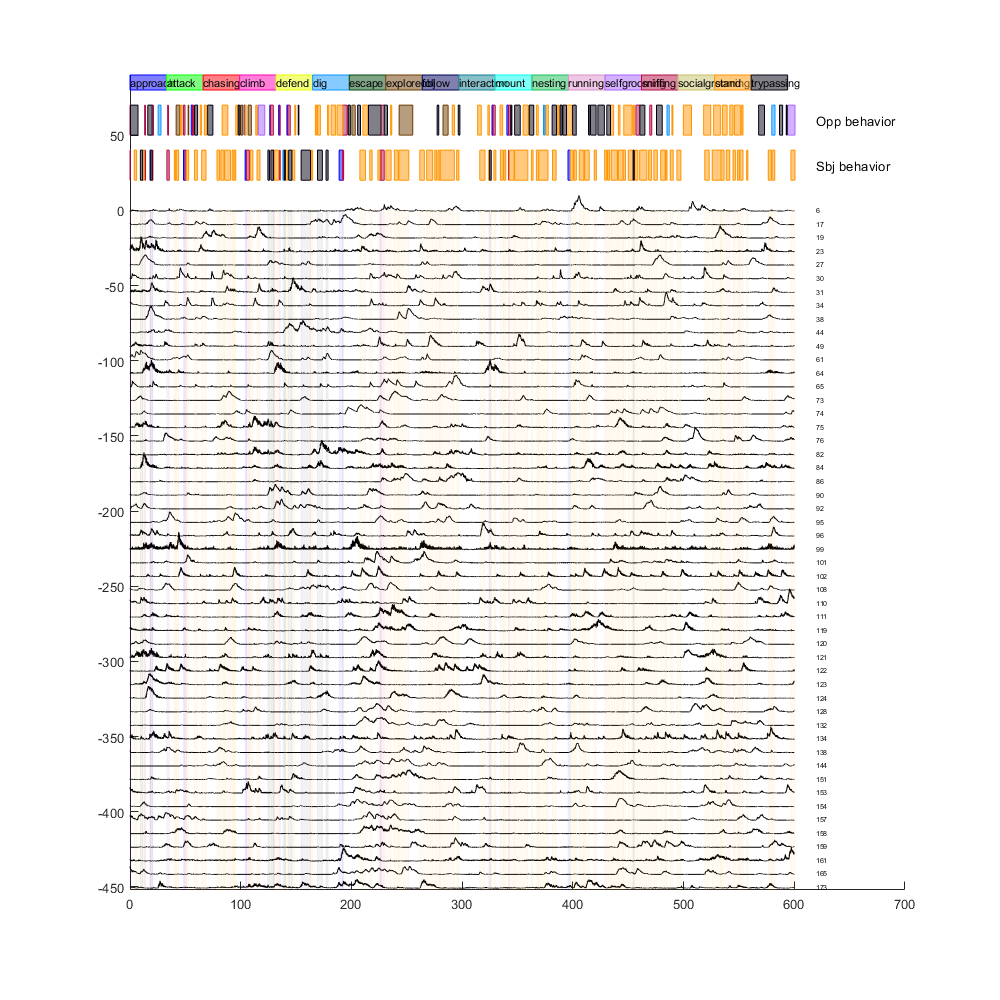

figure,
PlotSelectedCells(E_struct{1}, posID1,false);

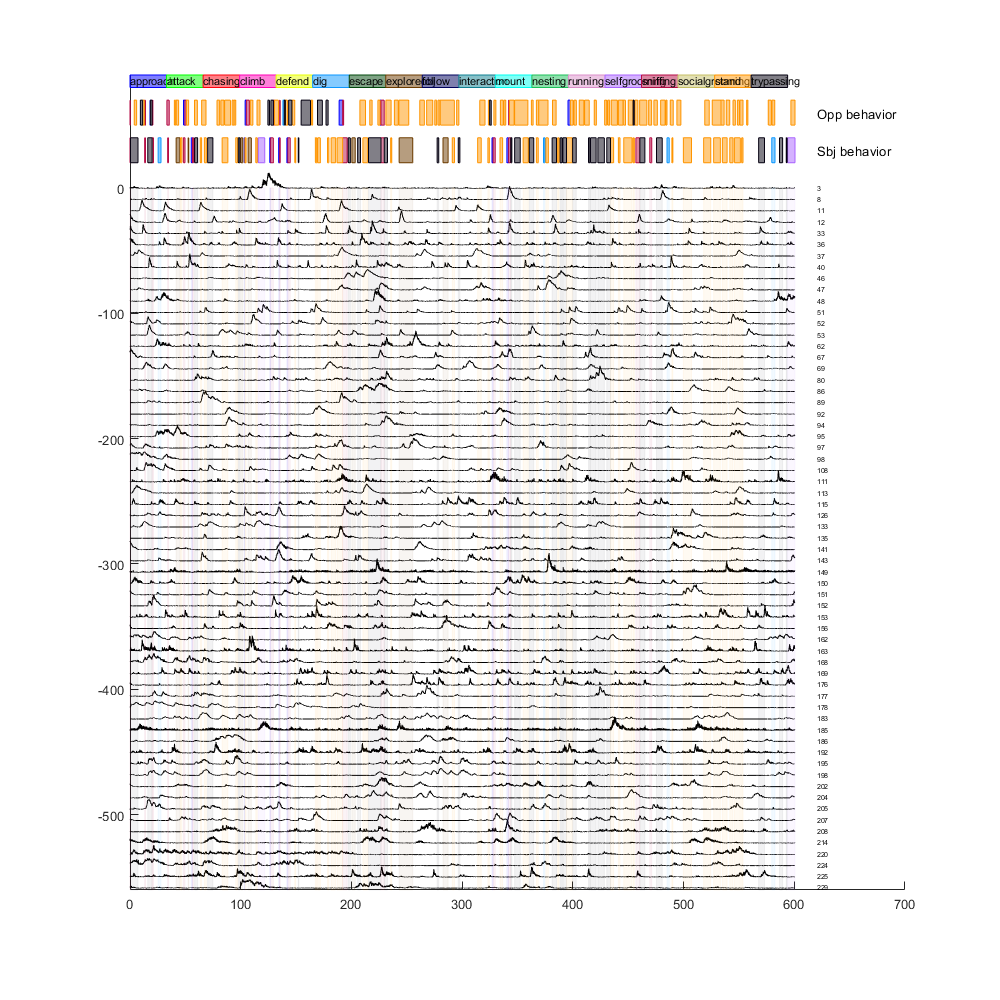

figure,
PlotSelectedCells(E_struct{2}, posID2, false);

l = min(size(DM1,1), size(DM2,1));
DM1 = DM1(1:l, :);
DM2 = DM2(1:l, :);
fprintf('pos vs pos\n');

pos vs pos


corr2(mean(DM1(:,posID1),2),mean(DM2(:,posID2),2))

ans = 0.3047

fprintf('pos_vs_nonpos\n');

pos_vs_nonpos


corr2(mean(DM1(:,posID1),2),mean(DM2(:,setdiff(1:size(DM2,2), posID2)),2))

ans = -0.0674

corr2(mean(DM2(:,posID2),2),mean(DM1(:,setdiff(1:size(DM1,2), posID1)),2))

ans = -0.2040

fprintf('nonpos_vs_nonpos\n');

nonpos_vs_nonpos


corr2(mean(DM2(:,setdiff(1:size(DM2,2), posID2)),2),mean(DM1(:,setdiff(1:size(DM1,2), posID1)),2))

ans = 0.0231

% calculate in vs out interaction corr
E_1_pos = E_struct{1};
E_1_neg = E_struct{1};
E_1_pos.DataMatrix = E_1_pos.DataMatrix(:,posID1);
E_1_neg.DataMatrix = E_1_neg.DataMatrix(:,setdiff(1:size(DM1,2),posID1));

E_2_pos = E_struct{2};
E_2_neg = E_struct{2};
E_2_pos.DataMatrix = E_2_pos.DataMatrix(:,posID2);
E_2_neg.DataMatrix = E_2_neg.DataMatrix(:,setdiff(1:size(DM2,2),posID2));

[inves_corr_in, inves_corr_out] = Corr_Behav(E_1_pos, E_2_pos, {'sniffing', 'sniffing'})

inves_corr_in = 0.6981

inves_corr_out = 0.2440

[inves_corr_in, inves_corr_out] = Corr_Behav(E_1_neg, E_2_neg, {'sniffing', 'sniffing'})

inves_corr_in = 0.0606

inves_corr_out = 0.0089

% Mouse1 Mouse2 at different behavior state
E_struct{1}.Behavior.EventNames

ans = 1×18 cell array
    {'attack'}    {'approach'}    {'chasing'}    {'dig'}    {'escape'}    {'sniffing'}    {'selfgrooming'}    {'socialgrooming'}    {'defend'}    {'exploreobj'}    {'climb'}    {'follow'}    {'mount'}    {'running'}    {'stand'}    {'nesting'}    {'interaction'}    {'trypassing'}


[inves_corr_in, inves_corr_out] = Corr_Behav(E_struct{1}, E_struct{2}, {'sniffing', 'sniffing'})

inves_corr_in = -0.1161

inves_corr_out = -0.0171

[inves_corr_in, inves_corr_out] = Corr_Behav(E_struct{1}, E_struct{2}, {'sniffing','approach,dig,escape,selfgrooming,stand'})

inves_corr_in = NaN

inves_corr_out = -0.0178

[inves_corr_in, inves_corr_out] = Corr_Behav(E_struct{1}, E_struct{2}, {'approach,dig,escape,selfgrooming,stand','sniffing'})

inves_corr_in = -0.5490

inves_corr_out = -0.0109

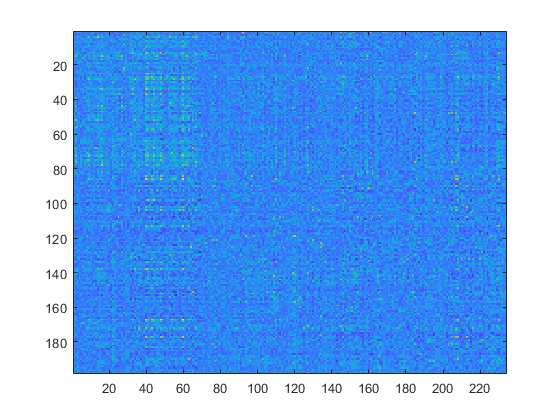

% corr matrix
cor_mat = zeros(size(DM1,2),size(DM2,2));
for i = 1:length(posID1)
    parfor j = 1:length(posID2)
        cor_mat(i,j) = corr2(DM1(:,posID1(i)), DM2(:,posID2(j)));
    end
end
negID1 = setdiff(1:size(DM1,2), posID1);
negID2 = setdiff(1:size(DM2,2), posID2);
for i = 1:length(posID1)
    parfor j = length(posID2)+1 : length(posID2)+length(negID2)
        cor_mat(i,j) = corr2(DM1(:,posID1(i)),DM2(:,negID2(j-length(posID2))));
    end
end
for i = length(posID1)+1 : length(posID1) + length(negID1)
    parfor j = 1:length(posID2)
        cor_mat(i,j) = corr2(DM1(:,negID1(i-length(posID1))), DM2(:, posID2(j)));
    end
end
for i = length(posID1)+1 : length(posID1) + length(negID1)
    parfor j = length(posID2)+1 : length(posID2)+length(negID2)
        cor_mat(i,j) = corr2(DM1(:,negID1(i-length(posID1))), DM2(:,negID2(j-length(posID2))));
    end
    
end
figure,
imagesc(cor_mat)

% a fake behav session as a control
% random_corr1 = []; % store pos vs pos, pos vs nonpos, nonpos vs nonpos 
% random_corr2 = []; % store pos invest corr in vs out, neg invest in vs out
for tt = 1:333
social_logicalo = circshift(social_logicalo, randperm(50000,1));

posID1 = [];
parfor p = 1:size(DM1,2)
    c = DM1(:,p);
    social_logical = social_logicalo(1:length(c));
    dt = [];
    for i = 1:3000
        temp = circshift(c,randperm(50000,1));
        dt = [dt, sum(temp(social_logical>0))];
    end
%     figure,
%     histogram(dt);
    if sum(c(social_logical>0)) >= quantile(dt, 0.5)
        posID1 = [posID1, p];
    end
end
posID2 = [];
parfor p = 1:size(DM2,2)
    c = DM2(:,p);
    social_logical = social_logicalo(1:length(c));
    dt = [];
    for i = 1:3000
        temp = circshift(c,randperm(50000,1));
        dt = [dt, sum(temp(social_logical>0))];
    end
%     figure,
%     histogram(dt);
    if sum(c(social_logical>0)) >= quantile(dt, 0.75)
        posID2 = [posID2, p];
    end
end
% figure,
% PlotSelectedCells(E_struct{1}, posID,false);
l = min(size(DM1,1), size(DM2,1));
DM1 = DM1(1:l, :);
DM2 = DM2(1:l, :);
fprintf('pos vs pos\n');
t1 = corr2(mean(DM1(:,posID1),2),mean(DM2(:,posID2),2));
fprintf('pos_vs_nonpos\n');
t2 = corr2(mean(DM1(:,posID1),2),mean(DM2(:,setdiff(1:size(DM2,2), posID2)),2));
t3 = corr2(mean(DM2(:,posID2),2),mean(DM1(:,setdiff(1:size(DM1,2), posID1)),2))
fprintf('nonpos_vs_nonpos\n');
t4 = corr2(mean(DM2(:,setdiff(1:size(DM2,2), posID2)),2),mean(DM1(:,setdiff(1:size(DM1,2), posID1)),2));
random_corr1 = [random_corr1; t1,t2,t3,t4];
% calculate in vs out interaction corr
E_1_pos = E_struct{1};
E_1_neg = E_struct{1};
E_1_pos.DataMatrix = E_1_pos.DataMatrix(:,posID1);
E_1_neg.DataMatrix = E_1_neg.DataMatrix(:,setdiff(1:size(DM1,2),posID1));

E_2_pos = E_struct{2};
E_2_neg = E_struct{2};
E_2_pos.DataMatrix = E_2_pos.DataMatrix(:,posID2);
E_2_neg.DataMatrix = E_2_neg.DataMatrix(:,setdiff(1:size(DM2,2),posID2));

[inves_corr_in1, inves_corr_out2] = Corr_Behav(E_1_pos, E_2_pos, {'investigation'},false);
[inves_corr_in3, inves_corr_out4] = Corr_Behav(E_1_neg, E_2_neg, {'investigation'},false);
random_corr2 = [random_corr2; inves_corr_in1,inves_corr_out2,inves_corr_in3,inves_corr_out4];
fprintf('%i finished \n', tt);

end

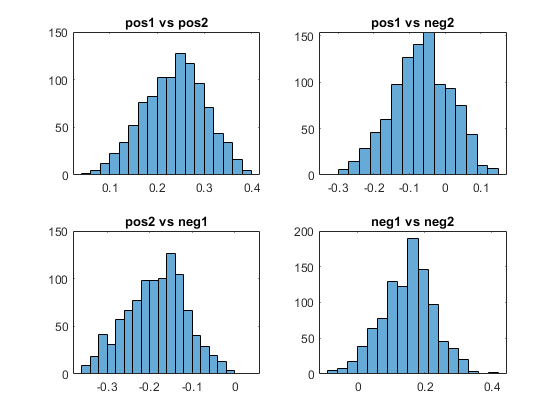

figure, 
subplot(2,2,1),histogram(random_corr1(:,1)); title('pos1 vs pos2');
subplot(2,2,2), histogram(random_corr1(:,2)); title('pos1 vs neg2');
subplot(2,2,3), histogram(random_corr1(:,3)); title('pos2 vs neg1');
subplot(2,2,4), histogram(random_corr1(:,4)); title('neg1 vs neg2');

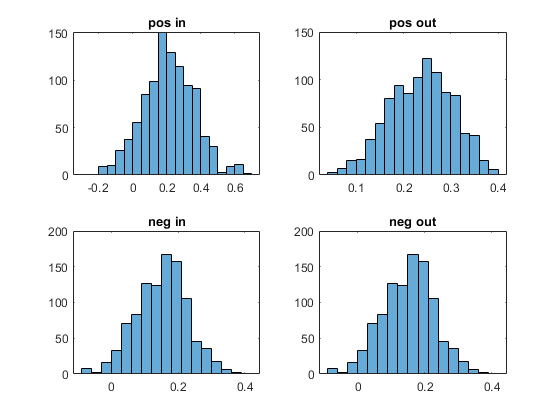


figure, 
subplot(2,2,1), histogram(random_corr2(:,1)); title('pos in');
subplot(2,2,2), histogram(random_corr2(:,2)); title('pos out');
subplot(2,2,3), histogram(random_corr2(:,4)); title('neg in');
subplot(2,2,4), histogram(random_corr2(:,4)); title('neg out');

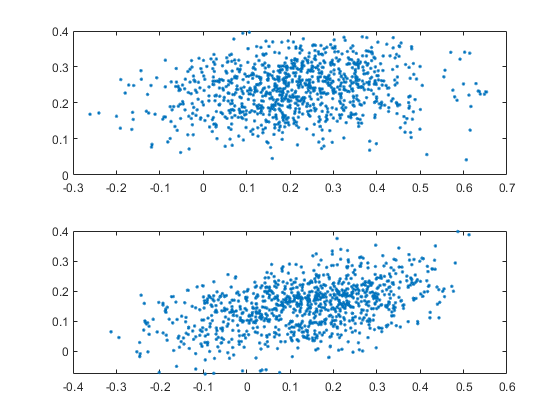

figure,subplot(2,1,1),plot(random_corr2(:,1), random_corr2(:,2),'.');
subplot(2,1,2),plot(random_corr2(:,3), random_corr2(:,4),'.');